clear 
clc

load('forcing_terms.mat')
load('test_functions2.mat')
load('myFunctions.mat')

c1 = 1e-4;
rho = 0.8;
btmax = 50;

% step for finite differences cases
h = 1e-8;

x0 = x_f13(1000);
f = f13;

gradf = 0;
Hessf = 0;
kmax = 1000;
tolgrad = 1.0E-7;

% max number of iterations for the pcg
pcg_maxit = 100;

### Run the Newton of f3

%fterms = @(gradf, x, k) 0.5;
%fterms = @(gradfk, k) min(0.5, sqrt(norm(gradfk)));
fterms = @(gradfk, k) min(0.5, norm(gradfk));

% options for finite differences
FDgrad = 'c';
FDHess = 'fw';

disp('***Newton F.D. options***')

***Newton F.D. options***


disp(['FDgrad: ', FDgrad])

FDgrad: c


disp(['FDHess: ', FDHess])

FDHess: fw



disp('***Newton: start***')

***Newton: start***



[xk, fk, gradfk_norm, k, xseq, btseq] = ...
    innewton_general(x0, f, gradf, Hessf, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit)

pcg converged at iteration 1 to a solution with relative residual 2.1e-05.
pcg converged at iteration 1 to a solution with relative residual 1.4e-05.
pcg converged at iteration 1 to a solution with relative residual 9e-05.
pcg converged at iteration 1 to a solution with relative residual 2.6e-05.
pcg converged at iteration 1 to a solution with relative residual 1.1e-06.
pcg converged at iteration 1 to a solution with relative residual 8.7e-10.
pcg converged at iteration 1 to a solution with relative residual 1.6e-14.


xk = 1.0e-13 *

    0.3186
   -0.3186
    0.3186
   -0.3186
    0.3186
   -0.3186
    0.3186
   -0.3186
    0.3186
   -0.3186


fk = 1.0150e-24

gradfk_norm = 2.0149e-12

k = 7

xseq =    -0.8000   -0.5482   -0.1535    0.0427   -0.0016    0.0000    0.0000
    0.8000    0.5482    0.1535   -0.0427    0.0016   -0.0000   -0.0000
   -0.8000   -0.5482   -0.1535    0.0427   -0.0016    0.0000    0.0000
    0.8000    0.5482    0.1535   -0.0427    0.0016   -0.0000   -0.0000
   -0.8000   -0.5482   -0.1535    0.0427   -0.0016    0.0000    0.0000
    0.8000    0.5482    0.1535   -0.0427    0.0016   -0.0000   -0.0000
   -0.8000   -0.5482   -0.1535    0.0427   -0.0016    0.0000    0.0000
    0.8000    0.5482    0.1535   -0.0427    0.0016   -0.0000   -0.0000
   -0.8000   -0.5482   -0.1535    0.0427   -0.0016    0.0000    0.0000
    0.8000    0.5482    0.1535   -0.0427    0.0016   -0.0000   -0.0000


btseq =      0     0     0     0     0     0     0



disp('***newton: finished')

***newton: finished


disp('***newton: results')

***newton: results


disp('*******')

*******


disp(['xk: ', mat2str(xk), '(actual minimum:[1: 1]);'])

xk: [3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.18588604454469e-14;-3.18588604454469e-14;3.1858

disp(['f(xk): ', mat2str(fk), '(actual minimum value: 0);'])

f(xk): 1.01498178480354e-24(actual minimum value: 0);


disp(['N of iterations: ', num2str(k), '/', num2str(kmax), ';'])

N of iterations: 7/1000;


disp('****')

****


Plots


disp_int = [-2 2];

f1_meshgrid = @(X,Y)reshape(f([X(:),Y(:)]'),size(X));
fcontour(f1_meshgrid, disp_int, 'Fill','on');

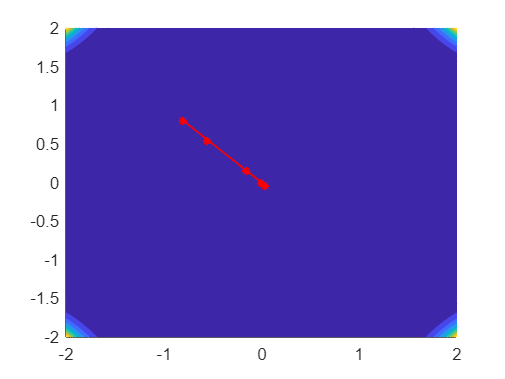

hold on
h = plot(xseq(1,:), xseq(2,:), '-*r', 'linewidth', 1, 'markersize', 5);
hold off

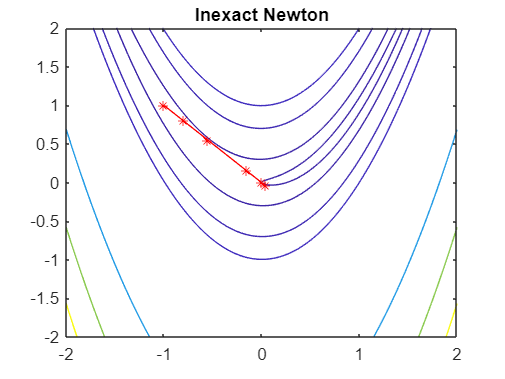

% creation of meshgrid for the contour-plot
[X1, Y1] = meshgrid(linspace(-2, 2, 500), linspace(-2, 2, 500));

% computation of the values of f for each point of the mesh
Z1 = (1-X1).^2 + 100 * (Y1-X1.^2).^2;

% Plots

% simple plot
fig1_n = figure();

% contour plot with curve levels for each point in xseq
[C1, ~] = contour(X1, Y1, Z1, [1, 10, 50, 100:1000:9000]);

hold on
% plot of the points in xseq
plot([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], '-*', color="r")

hold off
title('Inexact Newton')